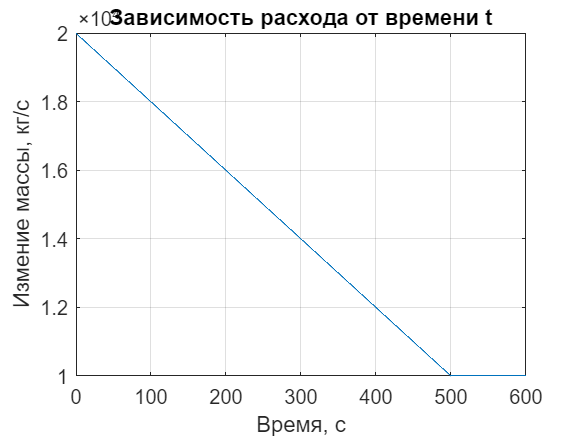

u0 = [20000 0 0 0 0 0 0 ];
options = odeset('MaxStep', 1);

[t, u] = ode45(@fcn, [0 600], u0, options);


plot(t, u(:, 1))
xlabel('Время, с');
ylabel('Измение массы, кг/с');
title('Зависимость расхода от времени t');
grid on;

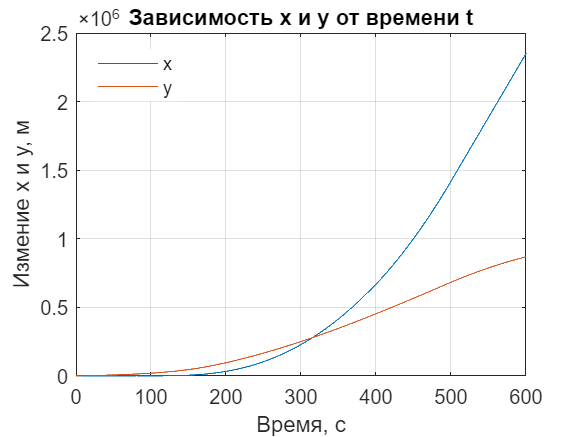


plot(t, u(:, 2))
xlabel('Время, с');
ylabel('Измение х и y, м');
title('Зависимость х и у от времени t');
grid on;
hold on;
plot(t, u(:, 3));
legend('x','y')
legend('Location','northwest')
legend('boxoff')
hold off;

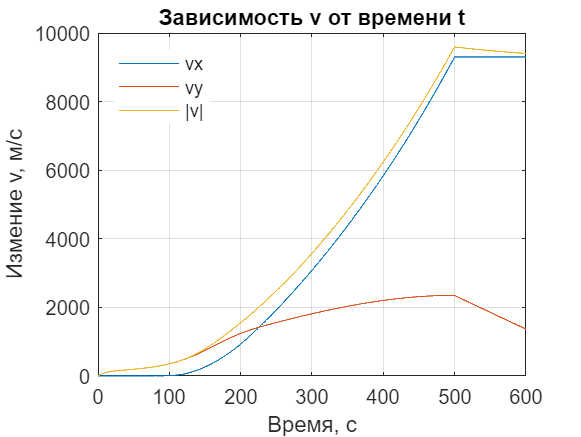


plot(t, u(:, 4))
xlabel('Время, с');
ylabel('Измение v, м/c');
title('Зависимость v от времени t');
grid on;
hold on;
plot(t, u(:, 5));
plot(t, sqrt((u(:, 4)).^2 + (u(:, 5)).^2));
legend('vx','vy','|v|')
legend('Location','northwest')
legend('boxoff')
hold off;

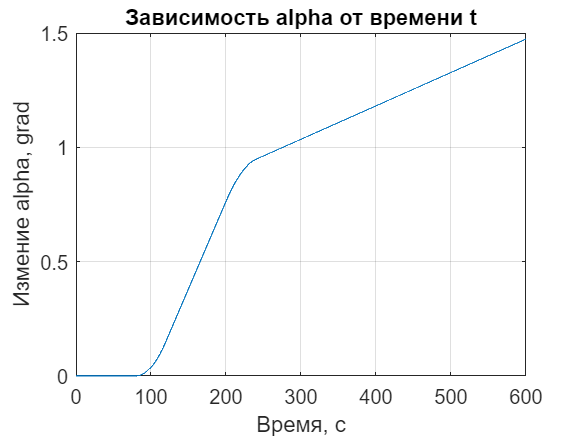



plot(t, u(:, 6))
xlabel('Время, с');
ylabel('Измение alpha, grad');
title('Зависимость alpha от времени t');
grid on;

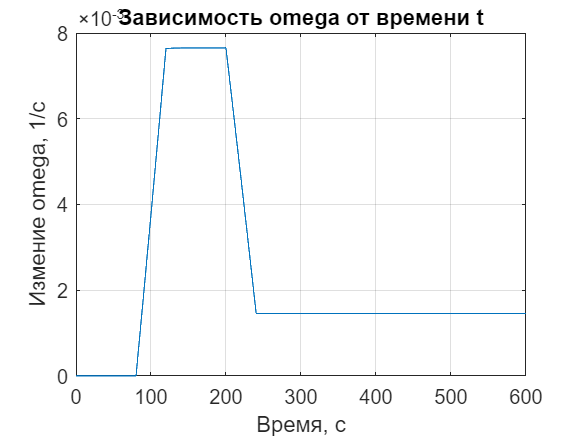


plot(t, u(:, 7))
xlabel('Время, с');
ylabel('Измение omega, 1/c');
title('Зависимость omega от времени t');
grid on;

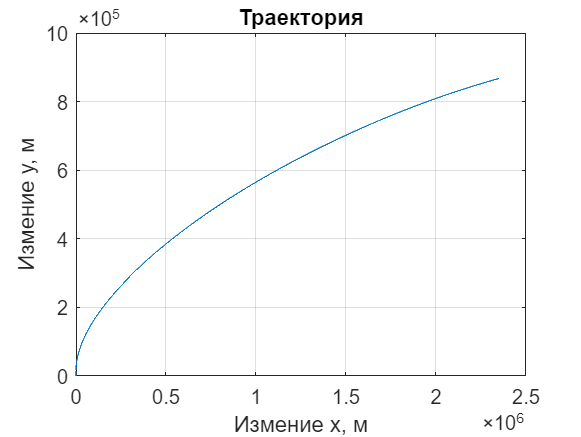


plot(u(: , 2), u(:, 3))
xlabel('Измение х, м');
ylabel('Измение y, м');
title('Траектория');
grid on;